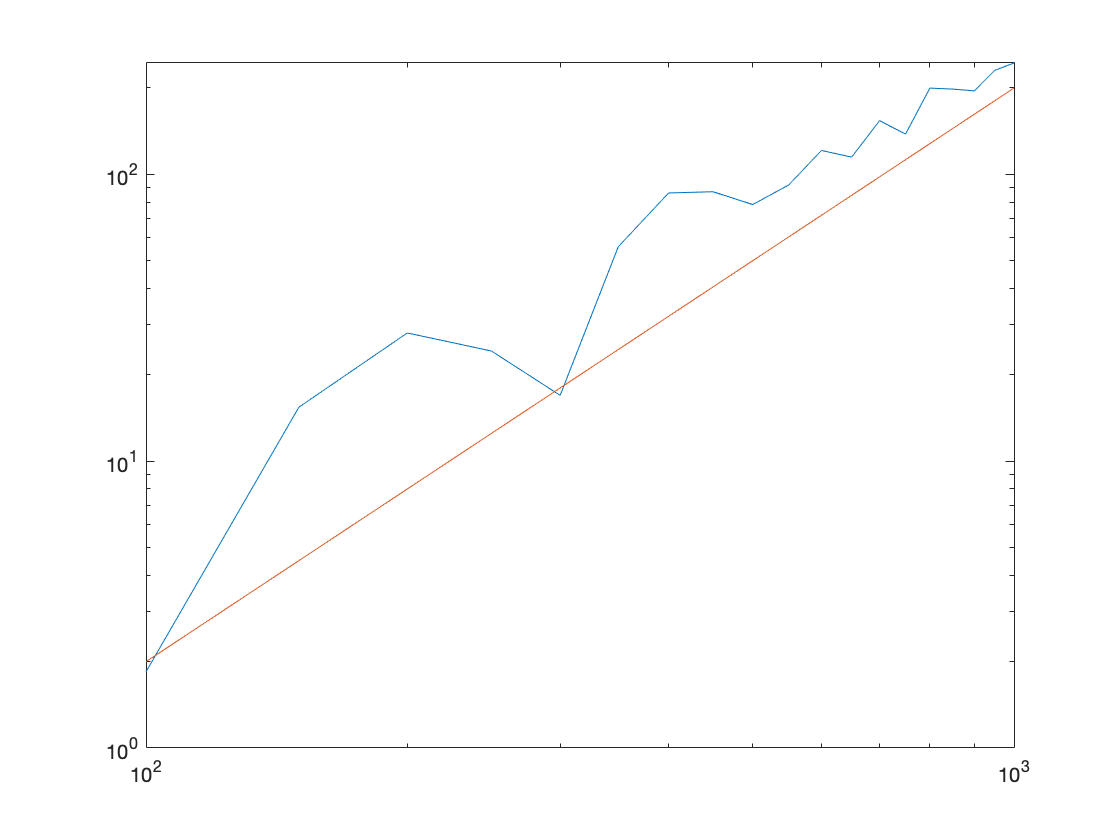

clc
clear all
close all

p = 1;
q = 1;
nmin = 100;
nmax = 1000;
dn = 50;

itermax = (nmax-nmin)/dn + 1;
timesband = zeros(itermax, 1);
timesnaive = zeros(itermax, 1);

iter = 1;
for n=nmin:dn:nmax
    
    A = rand(n, n);
    b = rand(n, 1);
    
    B = zeros(n, n);
    for k=1:n-1
        for i=k:min(k+q, n)
            for j=k:min(k+p, n)
                B(i, j) = A(i, j);
            end
        end
    end

    tic
    linear_ngaussel_banded(A, b, p, q);
    timesband(iter) = toc;
    
    tic
    linear_ngaussel(A, b);
    timesnaive(iter) =  toc;
    
    iter = iter + 1;
end

loglog([nmin:dn:nmax], timesnaive./timesband, [nmin:dn:nmax], ([nmin:dn:nmax].^2)./5000)